# Q4(a)

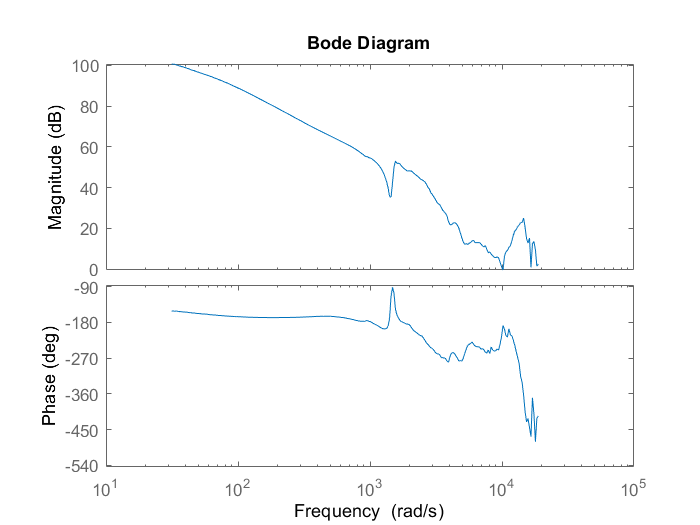

load respdata.mat;

[response,freq] = frdata(sys);
resp = mean(response,4);

resp_avg = frd(resp,freq);
bode(resp_avg)


Gnom = fitfrd(resp_avg,14,[],[],2);
isstable(Gnom)

ans = logical
   1


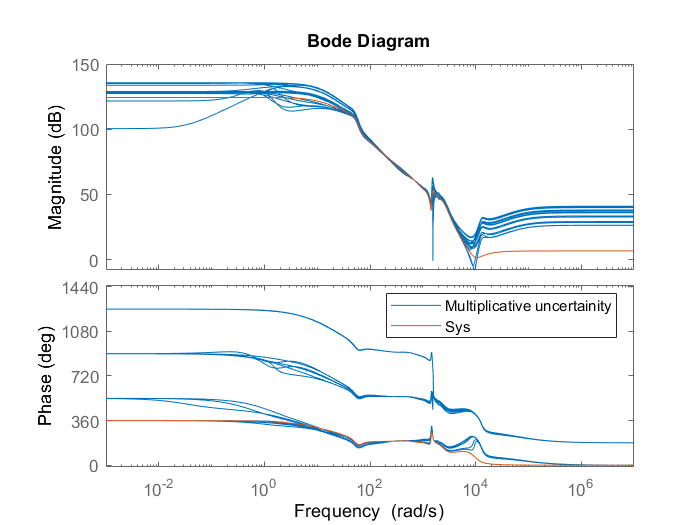

[P,info] = ucover(sys,Gnom,12,'InputMult');
Wt = info.W1;
bode(P,Gnom)
legend('Multiplicative uncertainity','Sys', "Location","best")

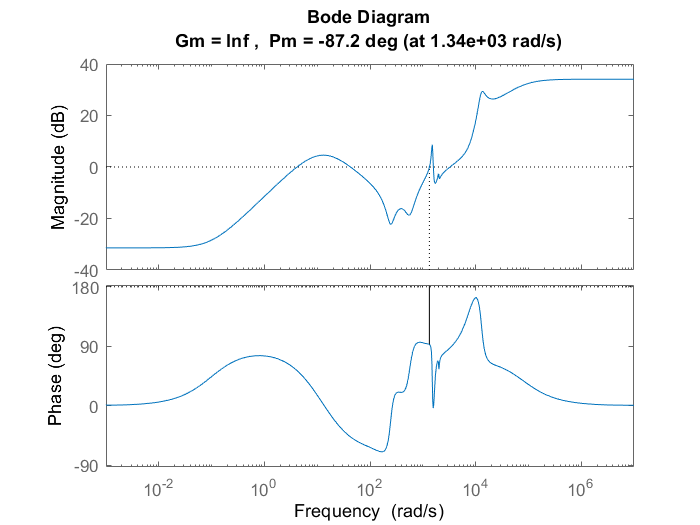


% Attenuate Large DC gain
s = tf('s');
Wt = Wt*(s+0.1)/(s+10);
margin(Wt)

del = ultidyn('del',1);
Gunc = Gnom*(1+Wt*del);

# Q4(b)

A = 100;
M = 2;

mu = 10;

BW_h = 10000;
BW_l = 0;
BW_new = (BW_h+BW_l)/2;
BW_try = BW_h;
while abs(BW_new-BW_try) > 1e-5
    BW_try = BW_new;
    Wp = (s/sqrt(M)+BW_try)^2/(s+BW_try/sqrt(A))^2;
    [K,CL,GAM] = mixsyn(Gnom,Wp,[],Wt);
    S = 1 - feedback(Gunc*K,1);
    [PERFMARG,info] = robustperf(Wp*S);
    mu = 1/PERFMARG.LowerBound;
    if mu < 1
        BW_l = BW_try;
    else
        BW_h = BW_try;
    end
    BW = BW_try;
    BW_new = 1/2*(BW_h+BW_l);
end
mu

mu = 0.9999

BW

BW = 1.7193

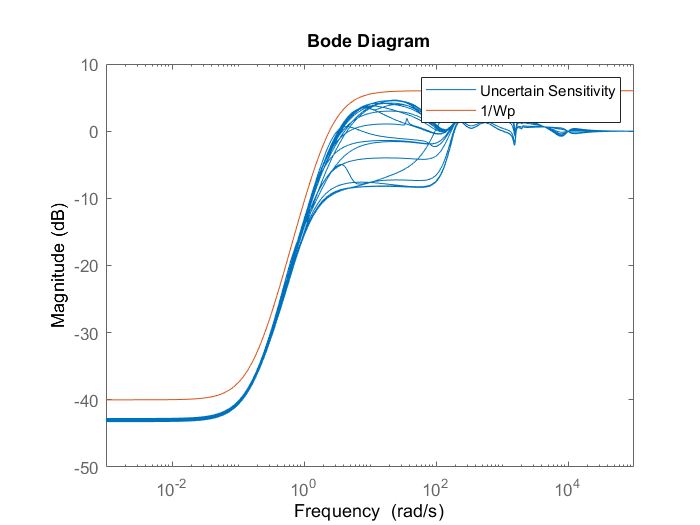

bodemag(S,1/Wp)
legend("Uncertain Sensitivity","1/Wp")

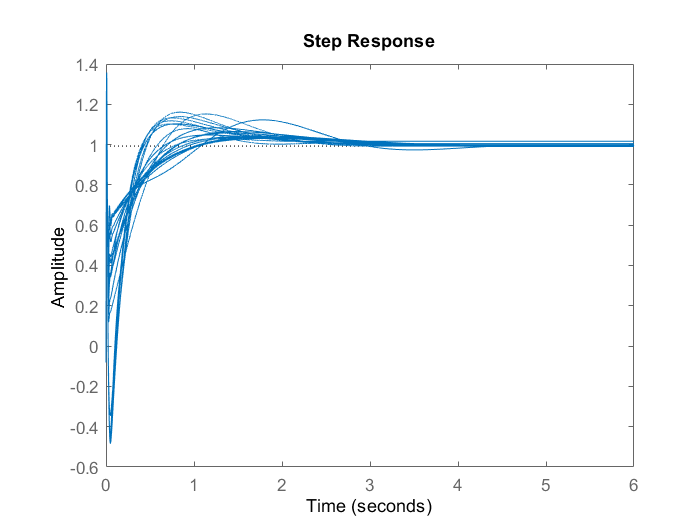

step(feedback(Gunc*K,1))